
Cycle-count IQR filter:


  Q1=5.00, Q3=11.00, IQR=6.00


  Bounds: [-4.00, 20.00]


  Subjects total=573 | outliers=21


  Outlier subjects (by cycle count):


    "MNC371"
    "MNC389"
    "MNC418"
    "MNC462"
    "MNC496"
    "MNC523"
    "MNC530"
    "MNC534"
    "MNC540"
    "MNC549"
    "MNC551"
    "MNC561"
    "MNC583"
    "SC4041EC"
    "SC4042EC"
    "SC4072EH"
    "SC4291GA"
    "SC4312EM"
    "SC4611EG"
    "SC4652EG"
    "SC4762EG"



  Dropped rows: 596 | kept rows: 4426 (from 5022)


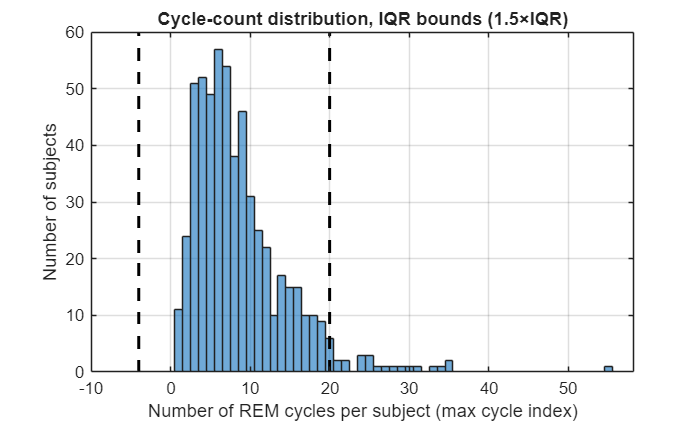

%==========================================================================
% Author:    Naghmeh Akhavan, PhD
% Affil.:    University of Michigan, Ann Arbor
% Contact:   nakhavan@umich.edu
%
%
% Last updated: March 2026
%==========================================================================

clear; clc;

%% ---------------- SETTINGS (folders + LW threshold) ----------------
combinedFolder  = 'C:\Users\naghm\OneDrive\Desktop\combined_out';
outDir          = fullfile(combinedFolder, 'tables_out');
if ~isfolder(outDir), mkdir(outDir); end

WAKE_BREAK_MIN  = 2;                 % minutes
WAKE_BREAK_SEC  = WAKE_BREAK_MIN*60; % seconds

%% ---------------- SUBJECT-LEVEL CYCLE-COUNT OUTLIER FILTER ----------------
DO_CYCLECOUNT_IQR_FILTER = true;
IQR_MULT = 1.5;

%% ---------------- LOAD UNFILTERED TABLE ----------------
matAll = fullfile(combinedFolder, 'Combined_BigResultTable.mat');
assert(isfile(matAll), 'Missing %s (run Step 3).', matAll);

S = load(matAll);
assert(isfield(S,'Combined_BigResultTable'), 'MAT lacks Combined_BigResultTable.');
T = S.Combined_BigResultTable;

%% ---------------- NORMALIZE COLUMNS (types + derived fields) -------------
T = normalize_cycles_table(T);

%% ========================================================================
%  SUBJECT-LEVEL OUTLIER FILTER BY # REM CYCLES (IQR rule)
%==========================================================================

if DO_CYCLECOUNT_IQR_FILTER
    vn = string(T.Properties.VariableNames);
    assert(ismember("REM_Cycle_Index", vn), 'REM_Cycle_Index column not found in table.');

    cycleID = string(T.REM_Cycle_Index);

    
    hasC = contains(cycleID, "_C");
    subjAll = strings(height(T),1);
    cnumAll = nan(height(T),1);

    subjAll(hasC) = extractBefore(cycleID(hasC), "_C");
    cnumAll(hasC) = str2double(extractAfter(cycleID(hasC), "_C"));

    ok = hasC & isfinite(cnumAll) & cnumAll > 0 & strlength(subjAll) > 0;

    subjUse = subjAll(ok);
    cnumUse = cnumAll(ok);

    if numel(subjUse) < 10
        warning('Cycle-count IQR filter skipped: too few valid REM_Cycle_Index entries after parsing.');
    else
        [G, subjList] = findgroups(subjUse);
        cyclesPerSubj = splitapply(@max, cnumUse, G);   

        Q1 = prctile(cyclesPerSubj, 25);
        Q3 = prctile(cyclesPerSubj, 75);
        IQRv = Q3 - Q1;

        lowerBound = Q1 - IQR_MULT*IQRv;
        upperBound = Q3 + IQR_MULT*IQRv;

        isOut  = (cyclesPerSubj < lowerBound) | (cyclesPerSubj > upperBound);
        outSubj = subjList(isOut);

        fprintf('\nCycle-count IQR filter:\n');
        fprintf('  Q1=%.2f, Q3=%.2f, IQR=%.2f\n', Q1, Q3, IQRv);
        fprintf('  Bounds: [%.2f, %.2f]\n', lowerBound, upperBound);
        fprintf('  Subjects total=%d | outliers=%d\n', numel(subjList), numel(outSubj));

        if ~isempty(outSubj)
            fprintf('  Outlier subjects (by cycle count):\n');
            disp(outSubj);

            % Drop ALL rows for outlier subjects
          
            if ismember("Subject_Index", vn) && any(strlength(string(T.Subject_Index))>0)
                subjT = string(T.Subject_Index);
            else
                subjT = extractBefore(string(T.REM_Cycle_Index), "_C");
            end

            dropRows = ismember(subjT, outSubj);

            nBefore = height(T);
            T = T(~dropRows, :);
            fprintf('  Dropped rows: %d | kept rows: %d (from %d)\n', ...
                sum(dropRows), height(T), nBefore);
        else
            fprintf('  No cycle-count outliers detected.\n');
        end

        
        figure('Color','w');
        histogram(cyclesPerSubj, 'BinMethod','integers');
        hold on; yl = ylim;
        plot([lowerBound lowerBound], yl, 'k--', 'LineWidth',1.8);
        plot([upperBound upperBound], yl, 'k--', 'LineWidth',1.8);
        ylim(yl); grid on; box on;
        xlabel('Number of REM cycles per subject (max cycle index)');
        ylabel('Number of subjects');
        title(sprintf('Cycle-count distribution, IQR bounds (%.1f×IQR)', IQR_MULT));
    end
end


%% ========================================================================
%  LONG-WAKE FILTERING
%==========================================================================

vn = string(T.Properties.VariableNames);
maxWakeCandidates = ["MaxWakeSec","MaxWake_s","MaxWakeInIREMSec","MaxWakeInIREM_s","MaxWakeBlockSec","MaxWakeBlock_s"];

if any(ismember(maxWakeCandidates, vn))
    cname = maxWakeCandidates(find(ismember(maxWakeCandidates, vn), 1, 'first'));
    maxWakeSec = double(T.(cname));
    dropFlag = maxWakeSec >= WAKE_BREAK_SEC;
    filterMsg = sprintf("max Wake block '%s' >= %gs", cname, WAKE_BREAK_SEC);
elseif ismember("Wake", vn)
    dropFlag = double(T.Wake) >= WAKE_BREAK_SEC;   
    filterMsg = sprintf("total Wake (fallback) >= %gs", WAKE_BREAK_SEC);
else
    dropFlag = false(height(T),1);
    filterMsg = "no MaxWake*/Wake — no filtering applied";
    warning('No MaxWake* or Wake column found; no long-wake filtering applied.');
end

% apply the filter and compute counts
Tall     = T;              % keep a reference for totals
T        = T(~dropFlag,:); % kept cycles
TotalAll = height(Tall);
Kept     = height(T);
Dropped  = sum(dropFlag);
DroppedPct = 100 * Dropped / max(TotalAll,1);

%% ---------------- BUILD POOLED ARRAYS (minutes) ----------------
REMpre_min = T.REMpre/60;
IREM_min   = T.IREM/60;

% Valid points: positive & finite
valid = isfinite(REMpre_min) & (REMpre_min > 0) & isfinite(IREM_min) & (IREM_min > 0);
fprintf('Total cycles: %d | Kept: %d | Dropped: %d (%.1f%%)  [%s]\n', ...
        TotalAll, Kept, Dropped, DroppedPct, filterMsg);

Total cycles: 4426 | Kept: 2951 | Dropped: 1475 (33.3%)  [total Wake (fallback) >= 120s]


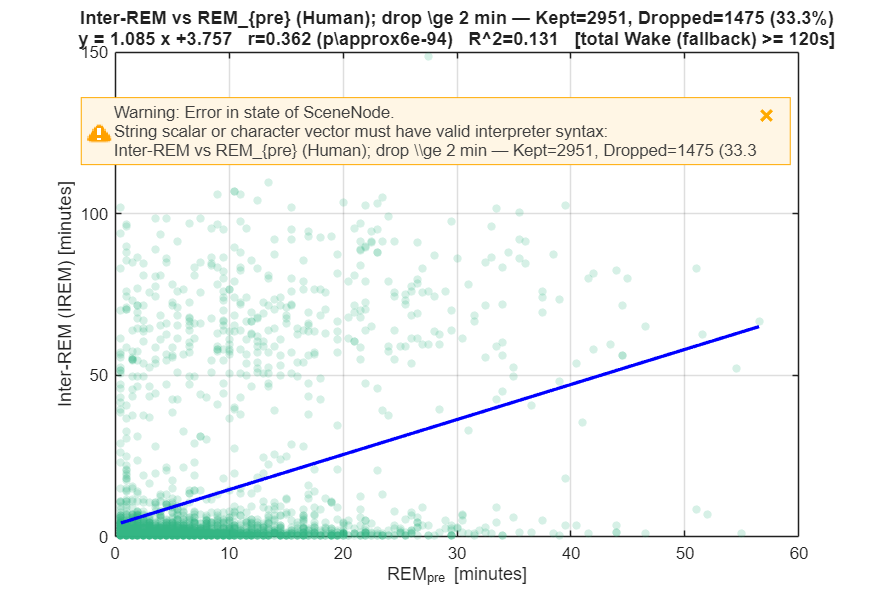


x = REMpre_min(valid); % X-axis = REMpre    [min]
y = IREM_min(valid);   % Y-axis = inter-REM [min]
n = numel(x);

if n < 2
    error('Not enough valid points after filtering (n=%d).', n);
end

%% ---------------- SIMPLE LINE FIT y = a*x + b ----------------
p  = polyfit(x, y, 1);          % [a b]
xx = linspace(min(x), max(x), 300);
yy = polyval(p, xx);

%% ---------------- PEARSON r + approx p-value + R^2 ----------------
C  = corrcoef(x, y);  r = C(1,2);
if n >= 4 && abs(r) < 1
    z = atanh(r) * sqrt(n - 3);
    pval = erfc(abs(z)/sqrt(2));
else
    pval = NaN;
end
R2 = r^2;

%% ---------------- PLOT ----------------
f1 = figure('Color','w','Position',[100 100 820 560], 'Name','Human: IREM vs REMpre');
h = scatter(x, y, 20, [0.20 0.70 0.50], 'filled');
set(h, 'MarkerEdgeColor', [0.20 0.70 0.50], ...
       'MarkerFaceAlpha', 0.20, ...
       'MarkerEdgeAlpha', 0.20);
hold on;
plot(xx, yy, 'b-', 'LineWidth', 2);
grid on; box on;


xlabel('REM_{pre} [minutes]');
ylabel('Inter-REM (IREM) [minutes]');
title(sprintf(['Inter-REM vs REM_{pre} (Human); drop \\ge %d min — Kept=%d, Dropped=%d (%.1f%%)\n' ...
               'y = %.3f x %+.3f   r=%.3f (p\\approx%.3g)   R^2=%.3f   [%s]'], ...
      WAKE_BREAK_MIN, Kept, Dropped, DroppedPct, p(1), p(2), r, pval, R2, filterMsg));


%% ========================================================================
%  FUNCTIONS
%==========================================================================

function T = normalize_cycles_table(T)
    % ensure subject and cycle IDs exist and are strings
    if ~ismember("Subject_Index", string(T.Properties.VariableNames))
        T.Subject_Index = strings(height(T),1);
    end
    T.Subject_Index = string(T.Subject_Index);

    if ~ismember("REM_Cycle_Index", string(T.Properties.VariableNames))
        T.REM_Cycle_Index = strings(height(T),1);
    end
    T.REM_Cycle_Index = string(T.REM_Cycle_Index);

    % Source (infer when missing)
    if ~ismember("Source", string(T.Properties.VariableNames))
        T.Source = strings(height(T),1);
    else
        T.Source = string(T.Source);
    end
    m = (T.Source=="" | ismissing(T.Source));
    T.Source(m & startsWith(T.Subject_Index,"MNC"))      = "MNC";
    T.Source(m & startsWith(T.Subject_Index,"SC"))       = "EDF";
    T.Source(m & startsWith(T.Subject_Index,"BitBrain")) = "BitBrain";
    T.Source(T.Source=="") = "Unknown";

    % Ensure numeric metric columns exist and are doubles
    need = ["REMpre","NREM","Wake","Movement","IREM"];
    for v = need
        if ~ismember(v, string(T.Properties.VariableNames))
            T.(v) = NaN(height(T),1);
        end
        T.(v) = double(T.(v));
    end
    % Rebuild IREM if needed/missing
    if all(isnan(T.IREM)) && all(ismember(["NREM","Wake","Movement"], string(T.Properties.VariableNames)))
        T.IREM = T.NREM + T.Wake + T.Movement;
    end

    % Species tag
    if ~ismember("Species", string(T.Properties.VariableNames))
        T.Species = repmat("Human", height(T), 1);
    else
        T.Species = string(T.Species);
        T.Species(T.Species=="") = "Human";
    end
end
